close all
clear
clc

clc
M = 32; % signal dimension
N = 2*M;% number of atoms in the expansion

C = nan(M, M); % matrix containing the standard basis (a kronecker delta in each column)
DCT = nan(M, M); % matrix containing the DCT basis (a DCT function in each column)

%% generate the 1D-DCT basis
disp('generating 1-D DCT basis')

generating 1-D DCT basis


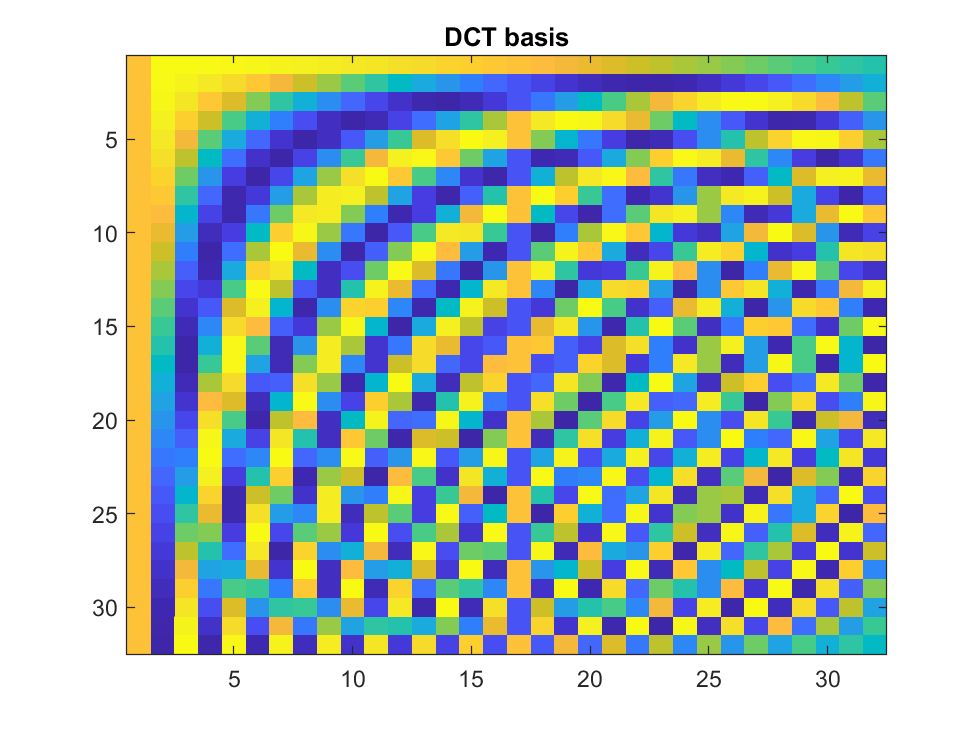

cnt = 1;
for ii = 1 : M
    a = zeros(1, M);
    a(ii) = 1;
    DCT(:, cnt) = idct(a)';
    cnt = cnt + 1;
end
figure(3), imagesc(DCT), title('DCT basis');


%% generate Standard orthonormal basis

disp('generating 1-D standard basis')

generating 1-D standard basis


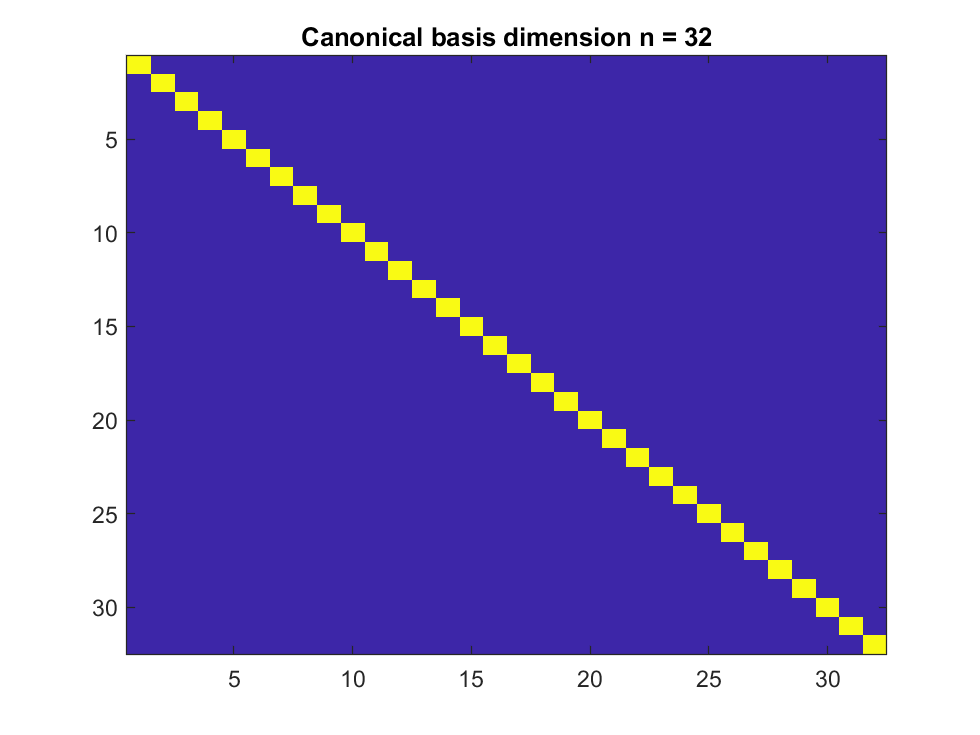

cnt = 1;
for ii = 1 : M
    a = zeros(1, M);
    a(ii) = 1;
    C(:, cnt) = a;
    cnt = cnt + 1;
end
figure(2), imagesc(C), title(['Canonical basis dimension n = ', num2str(M)]);

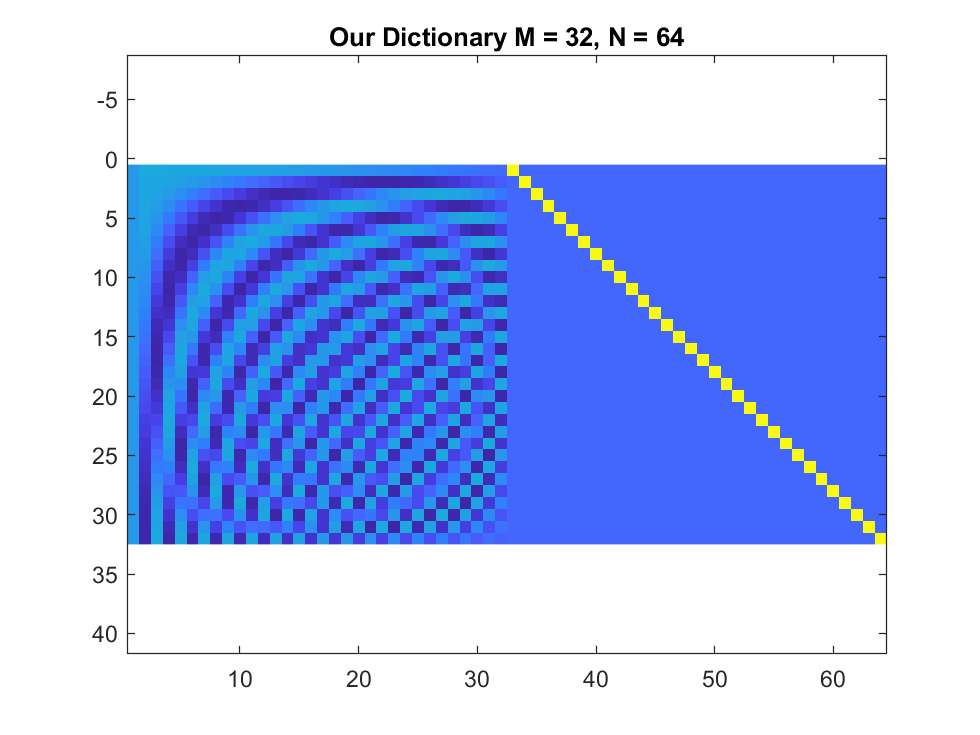


%% define the dictionary D = [DCT, C];
D = [DCT, C];
figure(3), imagesc(D), title(['Our Dictionary M = ', num2str(M), ', N = ', num2str(N)]);
axis equal

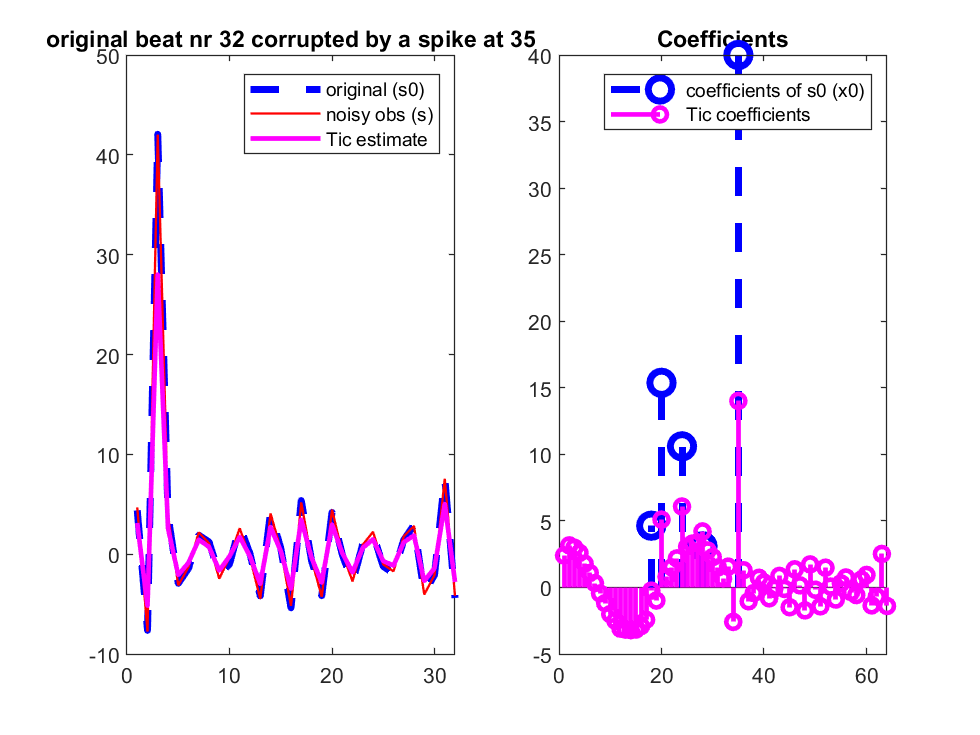


%% generate signals that are sparse w.r.t. [C, D], i.e. add a spike to the sum of few DCT atoms
% add a spike to s that is sparse w.r.t. D, bear in mind that the spike is to be considered a signal to be reconstructed,
% rather than noise

L = 5;
sigma_noise = 0.2;

% generate a signal that is sparse w.r.t. D

% randomly define the sparse representation w.r.t. [DCT,C]
% L - 1 nonzero coeff w.r.t DCT, 1 nonzero coeff w.r.t C (spike)
x0 = zeros(N, 1); 
values = 1./exprnd(0.2, 1, L-1);
indexes = randsample(M, L-1);
x0(indexes) = values;
% C coeff
spikeLocation = randsample(M:N, 1);
x0(spikeLocation) = 40;

s0 = D * x0;

% add noise
s = s0 + random('normal', 0, sigma_noise, size(s0));


%% Tichonov regularization
lmbda = 1;
% compute the representation by using the tichonov regularization
x_tic = (D'*D + lmbda*eye(N))^(-1)*D'*s;

% sinthesis: reconstruct the signal
s_hat_tic = D * x_tic;


%% show the result
LN_WDT = 2;
MRK_SZ = 10;

figure(5)
subplot(1,2,1)
plot(s0, 'b--',  'LineWidth', LN_WDT + 1),
hold on
plot(s, 'r-',  'LineWidth', LN_WDT -1),

plot(s_hat_tic, 'm-', 'LineWidth', LN_WDT),
title(['original beat nr ', num2str(ii), ' corrupted by a spike at ', num2str(spikeLocation)]);
hold off
legend('original (s0)', 'noisy obs (s)', 'Tic estimate')

subplot(1,2,2)
stem(find(x0 ~= 0), x0(x0~= 0), 'b--',  'LineWidth', LN_WDT + 1, 'MarkerSize', MRK_SZ),
hold on
stem(find(x_tic ~= 0), x_tic(x_tic ~= 0), 'm-', 'LineWidth', LN_WDT),
title('Coefficients')
hold off
legend('coefficients of s0 (x0)', 'Tic coefficients')



%% Orthogonal Matching Pursuit

% initialization
x_OMP = zeros(N,1);

% initialize the residual, namely the components of the signals that can not be represented (here the signal at the very beginning)
r = s;

% initialize the norm of the resiudal (components not represented by the coefficients)
l = 1;
resNorm = 0;
resNorm(l) = norm(r,2);

% initialize the support set
omega = zeros(N,1);
MINIMUM_RES_NORM = 0.01;
matrix = zeros(N,1);

while resNorm(l)>MINIMUM_RES_NORM && l<L + 1
    
    
    %% SWEEP STEP: look for the column of D that matches at best noisySignal
    % compute the residual w.r.t. each column of D
    for j = 1 : N
        % For each direction dj compute the error
        % A large value is set for the direction that are already
        % in the active set in order to exclude them from the minimization
        % problem
        if omega(j) == 0
            e(j) = resNorm(l)^2 - (r' * D(:,j))^2;
        else
            e(j) = 9999;
        end
        
    end
    % find the column of D that matches at best r, i.e. jStar = argmin(e(j))
    [~,jStar] = min(e);
    
    % UPDATE the support set
    omega(jStar) = 1;
    matrix = diag(omega);
    matrix = matrix(:,omega == 1);
    
    % update the coefficients by solving the least square problem min ||D_omega x - s ||
    x_OMP = linsolve(((D*matrix)'*(D*matrix)),(D*matrix)' * s);
    
    % remove the signal we have so far represented in x_OMP (update the residual)
    r = s - D*matrix*x_OMP;% component that cannot be captured by the signal (the signal at the very beginning)
    
    l = l + 1;
    
    % update the residual norm
    resNorm(l) = norm(r, 2);
end
l

l = 6

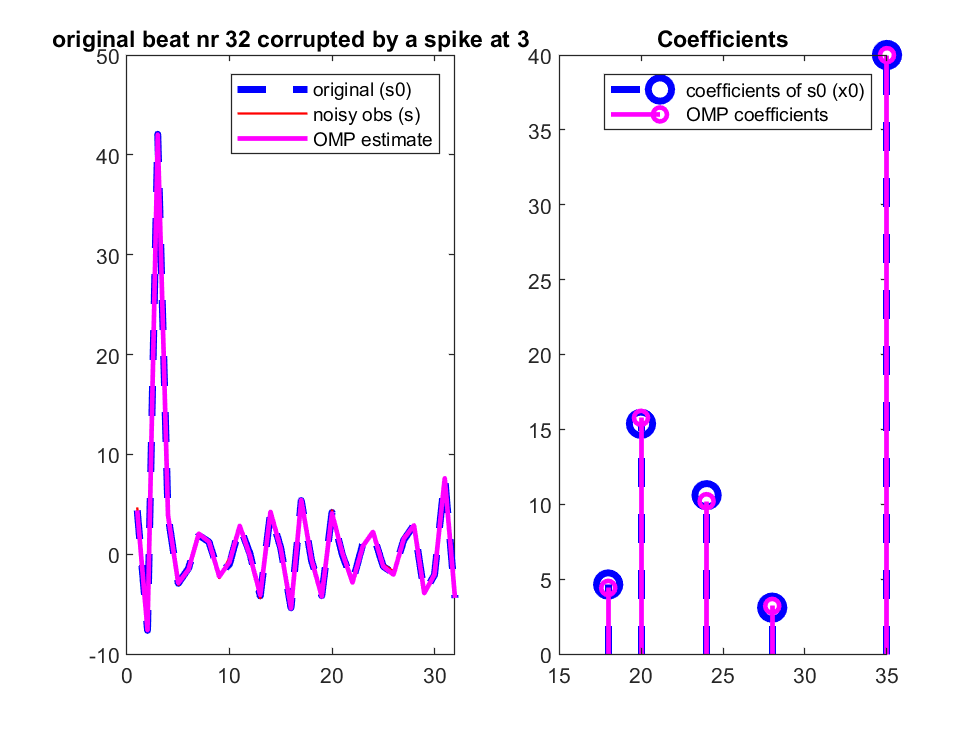

% invert the transformation to reconstruct the patch
s_hat_OMP = (D*matrix) * x_OMP;

% those part of the signal that have not been modeled by s_hat (i.e. the projection on the subspace of the L most
% involved coefficients) corresponds to the norm of the residual
resNorm_OMP = resNorm(l);

%% show the result
LN_WDT = 2;
MRK_SZ = 10;

figure(11)
subplot(1,2,1)
plot(s0, 'b--',  'LineWidth', LN_WDT + 1),
hold on
plot(s, 'r-',  'LineWidth', LN_WDT -1),

plot(s_hat_OMP, 'm-', 'LineWidth', LN_WDT),
title(['original beat nr ', num2str(ii), ' corrupted by a spike at ', num2str(spikeLocation- M)]);
hold off
legend('original (s0)', 'noisy obs (s)', 'OMP estimate')

subplot(1,2,2)
stem(find(x0 ~= 0), x0(x0~= 0), 'b--',  'LineWidth', LN_WDT + 1, 'MarkerSize', MRK_SZ),
hold on
x_OMP = matrix*x_OMP;
stem(find(x_OMP ~= 0), x_OMP(x_OMP ~= 0), 'm-', 'LineWidth', LN_WDT),
title('Coefficients')
hold off
legend('coefficients of s0 (x0)', 'OMP coefficients')

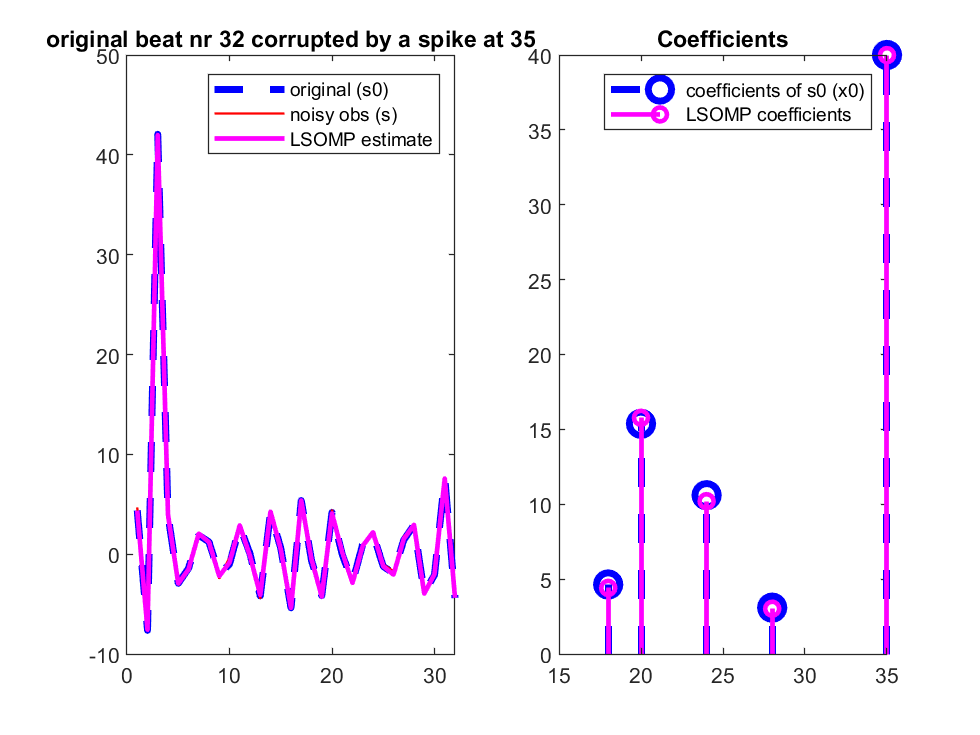

%% Least Squares Orthogonal Matching Pursuit

% initialization
x_LSOMP =  zeros(N,1);

% initialize the residual, namely the components of the signals that can not be represented (here the signal at the very beginning)
r = s;
l = 1;

% initialize the norm of the resiudal (components not represented by the coefficients)
resNorm(l) = norm(r, 2);

% initialize the support set
omega = zeros(N,1);
MINIMUM_RES_NORM = 0.01;
while resNorm(l) > MINIMUM_RES_NORM && l<L+1 %enter loop condition
    % SWEEP STEP: find the best column by solving the LS problem
    if l == 1
        % at the first iteration perform the usual sweep step
        for j=1:N
            e(j) = resNorm(l)^2 - (r' * D(:,j))^2;
        end
        % find the column of D that matches at best r, i.e. jStar = argmin(e(j))
        [~,jStar] = min(e);
    
        % UPDATE the support set
        omega(jStar) = 1;
        %% UPDATE the support set the jStar coefficient by *summing* the new component dj' r^(i) / || dj ||^2
        x_LSOMP(jStar) = x_LSOMP(jStar) + r'*D(:,jStar);
    
        % remove the signal we have so far represented in coeff_MP (update the residual)
        r =  s - D * x_LSOMP;% component that cannot be captured by the signal (the signal at the very beginning)    
        % update the residual norm
        resNorm(l) = norm(r, 2);
        
    else
        % perform the sweep step by solving the LS problem

        Dw = D * matrix;
        Xw = zeros(sum(omega == 1),N);
        
        for j=1:N
            if (omega(j) == 0)
                temp = [Dw' * Dw, Dw' * D(:,j); D(:,j)' * Dw, D(:,j)' * D(:,j)];
                LSsol = temp^(-1) * [Dw'*s; D(:,j)'*s];
                Xw(:,j) = LSsol(1:end-1);
                zj = LSsol(end);
                
                e(j) = norm([Dw, D(:,j)] * [Xw(:,j); zj] - s, 2);
            else
                e(j) = 999;
            end
        end
        
        
        [~,jStar] = min(e);
        % UPDATE the support set with the jStar coefficient
        omega(jStar) = 1;

        % update the coefficients by solving the least square problem min ||D_omega x - s ||
        x_LSOMP = matrix* Xw(:,jStar);
        x_LSOMP(jStar) = x_LSOMP(jStar) + r'*D(:,jStar);
    end 
    

    matrix = diag(omega);
    matrix = matrix(:,omega == 1);
    % remove the signal we have so far represented in x_LSOMP (update the residual)
    r = s - D*x_LSOMP; % component that cannot be captured by the signal (the signal at the very beginning)
    
    l = l + 1;
    
    % update the residual norm
    resNorm(l) = norm(r, 2);
end

% invert the transformation to reconstruct the patch
s_hat_LSOMP = D*x_LSOMP;

% those part of the signal that have not been modeled by s_hat (i.e. the projection on the subspace of the L most
% involved coefficients) corresponds to the norm of the residual
resNorm_LSOMP = resNorm(l);

%% show the result
LN_WDT = 2;
MRK_SZ = 10;

figure(17)
subplot(1,2,1)
plot(s0, 'b--',  'LineWidth', LN_WDT + 1),
hold on
plot(s, 'r-',  'LineWidth', LN_WDT -1),

plot(s_hat_LSOMP, 'm-', 'LineWidth', LN_WDT),
title(['original beat nr ', num2str(ii), ' corrupted by a spike at ', num2str(spikeLocation)]);
hold off
legend('original (s0)', 'noisy obs (s)', 'LSOMP estimate')

subplot(1,2,2)
stem(find(x0 ~= 0), x0(x0~= 0), 'b--',  'LineWidth', LN_WDT + 1, 'MarkerSize', MRK_SZ),
hold on
stem(find(x_LSOMP ~= 0), x_LSOMP(x_LSOMP ~= 0), 'm-', 'LineWidth', LN_WDT),
title('Coefficients')
hold off
legend('coefficients of s0 (x0)', 'LSOMP coefficients')

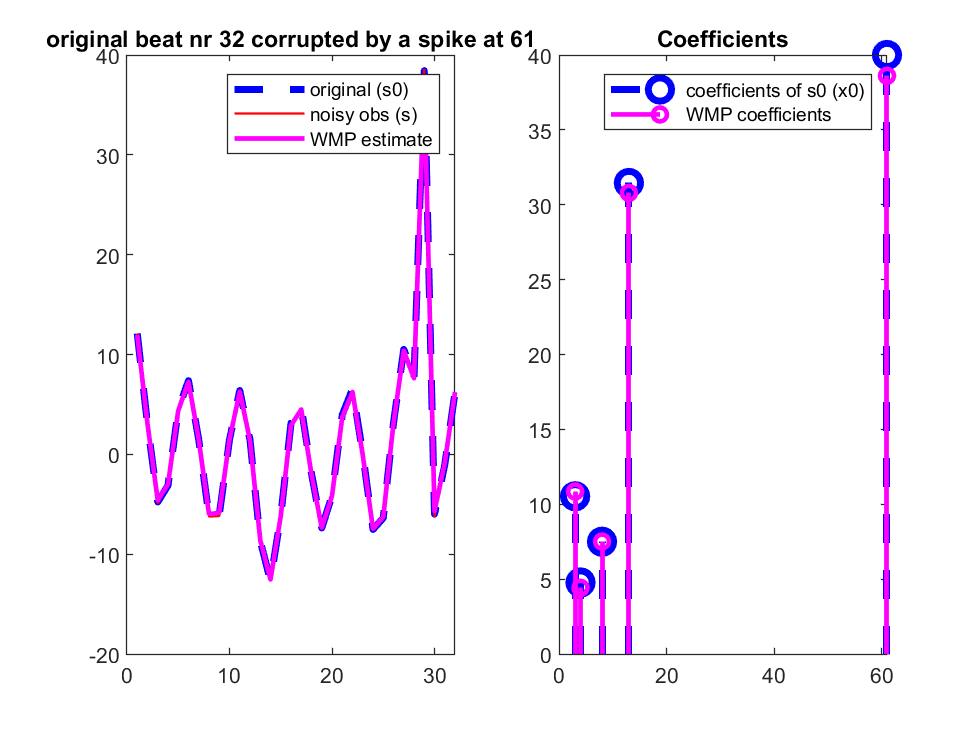


%% Weak Matching Pursuit
% initialization
x_WMP = zeros(N, 1);

% initialize the residual, namely the components of the signals that can not be represented (here the signal at the very beginning)
r = s;

l = 1;
% initialize the norm of the resiudal (components not represented by the coefficients)
resNorm(l) = norm(r, 2);

MINIMUM_RES_NORM = 0.01;
%portion of residual to decrease to break from the loop on the columns
t = 0.9;

% WMP Starts
% WMP loop starts.
% stoppint criteria: continue until the sparsity of the representation reaches L 
%                    or as long as resNorm(l) is above a minimum value
%                    or as long as a maxium number of iterations have been reached
thr = 1;
maxiter = 100;
while sum(x_WMP ~= 0) < L && resNorm(l) >MINIMUM_RES_NORM && l <maxiter
    
    
    % SWEEP STEP: look for the column of D that matches at best noisySignal
    % compute the residual w.r.t. each column of D
    % if the residual decreases enough break the loop
    e = 0;
    for j = 1 : N
        e(j) = resNorm(l)^2 - (r'*D(:,j))^2;
        if e(j) < thr
            break;
        end
    end
    [~,jStar] = min(e);
    % UPDATE the support set the jStar coefficient by *summing* the new component dj' r^(i) / || dj ||^2
    x_WMP(jStar) = x_WMP(jStar) + r'*D(:,jStar);
    
    % remove the signal we have so far represented in x_WMP (update the residual)
    r = s - D*x_WMP;% component that cannot be captured by the signal (the signal at the very beginning)
    
    l = l + 1;
    
    % update the residual norm
    resNorm(l) = norm(r, 2);
end

% invert the transformation to reconstruct the patch
s_hat_WMP = D*x_WMP;

% those part of the signal that have not been modeled by s_hat (i.e. the projection on the subspace of the L most
% involved coefficients) corresponds to the norm of the residual
resNorm_WMP = norm(s - s_hat_WMP, 2);

%% show the result
LN_WDT = 2;
MRK_SZ = 10;

figure(25)
subplot(1,2,1)
plot(s0, 'b--',  'LineWidth', LN_WDT + 1),
hold on
plot(s, 'r-',  'LineWidth', LN_WDT -1),

plot(s_hat_WMP, 'm-', 'LineWidth', LN_WDT),
title(['original beat nr ', num2str(ii), ' corrupted by a spike at ', num2str(spikeLocation)]);
hold off
legend('original (s0)', 'noisy obs (s)', 'WMP estimate')

subplot(1,2,2)
stem(find(x0 ~= 0), x0(x0~= 0), 'b--',  'LineWidth', LN_WDT + 1, 'MarkerSize', MRK_SZ),
hold on
stem(find(x_WMP ~= 0), x_WMP(x_WMP ~= 0), 'm-', 'LineWidth', LN_WDT),
title('Coefficients')
hold off
legend('coefficients of s0 (x0)', 'WMP coefficients')